**Grupo 8: Ana Robledano Abasolo, Alfredo Robledano Abasolo, **

**Melani Tatayo Culchas, Rubén Sierra Serrano**

Fecha: 29/03/2023

# **Ejercicio 1**

## T5.1. Polinomio de ajuste

clear, clc % Limpieza del entorno de trabajo

a)  Crea una función de Matlab que calcule el polinomio de ajuste por mínimos cuadrados para un conjunto de datos.

- Véase PoliMulti.m

b) Emplea la función del apartado a) para resolver la siguiente cuestión:

 Dados los siguientes datos obtenidos en un experimento:

 

x = [-.04, .93, 1.95, 2.90, 3.83, 5, 5.98, 7.05, 8.21, 9.08, 10.09];
y = [-8.66, -6.44, -4.36, -3.27, -0.88, 0.87, 3.31, 4.63, 6.19, 7.40, 8.85];

Determina el grado del polinomio que mejor se ajusta a los datos (desviación estándar menor).

n = numel(x);
desv_std = zeros(1, n-1);
for i = 1: n-1
    [~, ~, s] = PoliMulti(x, y, i);
    desv_std(i) = s;
end

Mostramos en una tabla los resultados:

grado = 1: n-1;
tabla_desviaciones = table( ...
    grado', num2str(desv_std', '%.4f'), ...
    VariableNames={'Grado', 'Desviación estándar'});
disp(tabla_desviaciones)

    Grado    Desviación estándar
    _____    ___________________

      1            0.2179       
      2            0.0852       
      3            0.2274       
      4            0.2534       
      5            0.2574       
      6            0.3286       
      7            0.3699       
      8            0.4531       
      9            0.6190       
     10               Inf       



Usando la función min de MATLAB podemos encontrar el grado de menor desviación estándar:

[min_desv, i] = min(desv_std);
fprintf("El grado del polinomio que mejor ajusta los datos es %d", i)

El grado del polinomio que mejor ajusta los datos es 2

fprintf("Presentando la menor desviación estándar de valor %f", min_desv)

Presentando la menor desviación estándar de valor 0.085167

Representa gráficamente el polinomio y los puntos de datos y calcula el error total

Hemos obtenido que el grado del polinomio que mejor ajusta es 2 (i = 2).

[p, error_total, ~] = PoliMulti(x, y, i);

Dibujamos los resultados obtenidos junto a los datos:

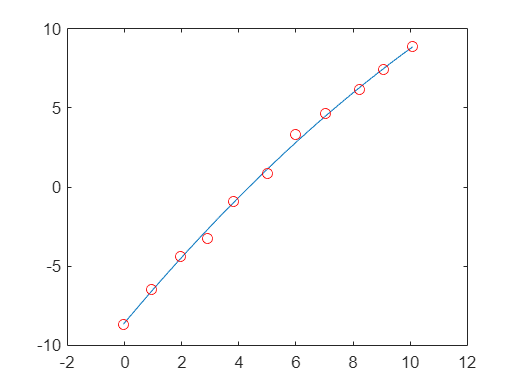

t = linspace(min(x),max(x));
plot(t, polyval(p, t));
hold on
plot(x, y, 'ro') % Datos iniciales
hold off

La función Polimulti() nos ha devuelto también el error total:

fprintf("El error total es: %f", error_total)

El error total es: 0.058027

# **Ejercicio 3**

## T5.3 Polinomio de interpolación de Lagrange

a) Desarrollar una función en Matlab que interpole un conjunto de puntos utilizando un polinomio de Lagrange. La función debe tener la forma:

`Yint=LagINT(x,y,Xint)`

La entrada de la función son las coordenadas de los puntos de datos dados (`x,y`) y la coordenada `Xint `en el punto en el que se debe calcular el valor interpolado de y. La salida de la función es el valor interpolado de y, `Yint.`

- `Véase LagINT.m`

b) Se da el conjunto de los siguientes cinco puntos de datos:

Emplear la función creada para representar gráficamente el polinomio de interpolación y los puntos dados. Calcular el valor interpolado en $x=3$

Preparamos el entorno de trabajo

clear
clc
close all

Zona de declaración de variables

x = [1 2 4 5 7];
y = [52 5 -5 -40 10];
Xint = 3;

Llamamos a la función y mostramos el resultado

Yint = LagINT(x,y,Xint);
fprintf("En x = 3 el polinomio interpolador toma el valor: %.3f", Yint)

En x = 3 el polinomio interpolador toma el valor: 6.000

Acomodamos los vectores para poder representar gráficamente el polinomio de interpolación 

xx = linspace(min(x),max(x));
yy = zeros(size(xx));
for i=1:length(xx)
    yy(i) = LagINT(x,y,xx(i));
end

Representación gráfica

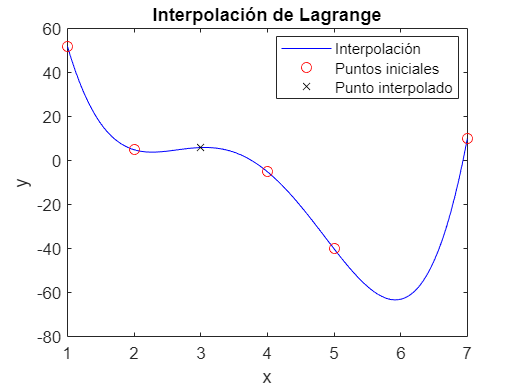

plot(xx,yy,"b-",x,y,"ro",Xint,Yint,"kx");
legend("Interpolación","Puntos iniciales","Punto interpolado","Location","best");
xlabel("x");
ylabel("y");
title("Interpolación de Lagrange");

# **Ejercicio 4**

## T5.4 Polinomio de interpolación de Newton

a) Escribe una función de MATLAB que interpole unos puntos dados utilizando el polinomio de Newton. Nómbrala:

`Yint` `=` `NewtonINT(x,y,Xint)`

La entrada de la función deben ser las coordenadas de los puntos de datos dados en dos vectores `x` e `y` y la coordenada `Xint` del punto en el que se va a interpolar. La salida de la función es el valor `Yint` del punto interpolado. Sugerencia: Inicia el programa calculando las primeras diferencias divididas, que luego se utilizan para calcular las diferencias divididas superiores. Asigna los valores a una matriz. Los coeficientes del polinomio (primera fila de la matriz) se asignan entonces a un vector.

- Véase `NewtonINT.m`

b) Dado el siguiente conjunto de puntos:

Emplea la función creada anteriormente para obtener el valor para $x=3$. Representa gráficamente el polinomio y los puntos interpolados

Preparamos el entorno de trabajo

clear
clc
close all

Zona de declaración de variables

x = [0 1 2 5.5 11 13 16 18];
y = [0.5 3.134 5.3 9.9 10.2 9.35 7.2 6.2];
Xint = 3;

Llamamos a la función y mostramos el resultado

Yint = NewtonINT(x,y,Xint);
fprintf("En x = 3 el polinomio interpolador toma el valor: %.3f", Yint)

En x = 3 el polinomio interpolador toma el valor: 7.072

Acomodamos los vectores para poder representar gráficamente el polinomio de interpolación 

xx = linspace(min(x),max(x));
yy = zeros(size(xx));
for i=1:length(xx)
    yy(i) = NewtonINT(x,y,xx(i));
end

Representación gráfica

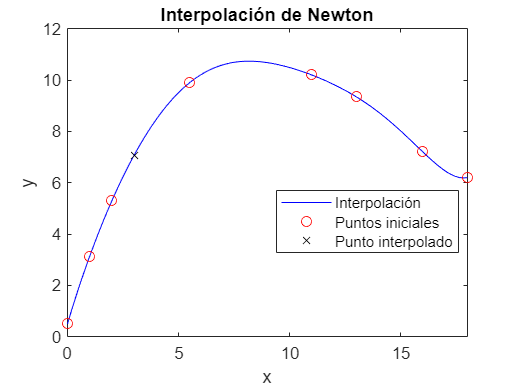

plot(xx,yy,"b-",x,y,"ro",Xint,Yint,"kx");
xlim([min(x), max(x)])
legend("Interpolación","Puntos iniciales","Punto interpolado","Location","best");
xlabel("x");
ylabel("y");
title("Interpolación de Newton");